clc
clear
bagReader = ros2bagreader(['D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_wolc90_1']);
baginfo = ros2("bag","info",'D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_wolc90_1')

baginfo = struct with fields:
                 Path: 'D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_wolc90_1'
      FileInformation: "nedc_wolc90_1_0.db3"
              Version: '4'
            StorageId: 'sqlite3'
             Duration: 67.1752
                Start: [1×1 struct]
                  End: [1×1 struct]
                 Size: 3792698
             Messages: 19217
                Types: [3×1 struct]
               Topics: [8×1 struct]
    CompressionFormat: 'none'
      CompressionMode: 'none'


% bagReader = ros2bagreader(['D:\experiment_22_11_2024\experiment_data_1_12_2024\nedc_wolc2']);
% baginfo = ros2("bag","info",'D:\experiment_22_11_2024\experiment_data_1_12_2024\nedc_wolc2')

in analysis if v<0.1, set v=0

%select current
bagSel = select(bagReader,"Topic","/motor_current")

bagSel =   ros2bagreader with properties:

           FilePath: 'D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_wolc90_1'
      AvailableBags: "nedc_wolc90_1_0.db3"
          StartTime: 1.7187e+09
            EndTime: 1.7187e+09
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [3359×3 table]
        NumMessages: 3359


msgsFiltered_curr = readMessages(bagSel);
curr_data=cell2mat(msgsFiltered_curr);
time=linspace(bagSel.StartTime, bagSel.EndTime, bagSel.NumMessages);
time_curr=time-time(1);
tb_curr=struct2table(curr_data);

%select voltage
bagSel = select(bagReader,"Topic","/motor_voltage")

bagSel =   ros2bagreader with properties:

           FilePath: 'D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_wolc90_1'
      AvailableBags: "nedc_wolc90_1_0.db3"
          StartTime: 1.7187e+09
            EndTime: 1.7187e+09
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [3359×3 table]
        NumMessages: 3359


msgsFiltered_voltage = readMessages(bagSel);
volt_data=cell2mat(msgsFiltered_voltage);
time=linspace(bagSel.StartTime, bagSel.EndTime, bagSel.NumMessages);
time_volt=time-time(1);
tb_volt=struct2table(volt_data);

%select motor_speed 
bagSel = select(bagReader,"Topic","/motor_erpm")

bagSel =   ros2bagreader with properties:

           FilePath: 'D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_wolc90_1'
      AvailableBags: "nedc_wolc90_1_0.db3"
          StartTime: 1.7187e+09
            EndTime: 1.7187e+09
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [3359×3 table]
        NumMessages: 3359


msgsFiltered_erpm = readMessages(bagSel);
erpm_data=cell2mat(msgsFiltered_erpm);
time=linspace(bagSel.StartTime, bagSel.EndTime, bagSel.NumMessages);
time_erpm=time-time(1);
tb_erpm=struct2table(erpm_data);

%select servo 
bagSel = select(bagReader,"Topic","/commands/servo/position")

bagSel =   ros2bagreader with properties:

           FilePath: 'D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_wolc90_1'
      AvailableBags: "nedc_wolc90_1_0.db3"
          StartTime: 1.7187e+09
            EndTime: 1.7187e+09
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [1699×3 table]
        NumMessages: 1699


msgsFiltered_servo = readMessages(bagSel);
servo_data=cell2mat(msgsFiltered_servo);
tb_servo=struct2table(servo_data);
time=linspace(bagSel.StartTime, bagSel.EndTime, bagSel.NumMessages);
time_servo=time-time(1);


% %select cmd_speed 
% bagSel = select(bagReader,"Topic","/")
% msgsFiltered_cmd_speed = readMessages(bagSel);
% curr_data=cell2mat(msgsFiltered_cmd_speed);
% tb_curr=struct2table(curr_data)

%select speed
bagSel = select(bagReader,"Topic","/odom")

bagSel =   ros2bagreader with properties:

           FilePath: 'D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_wolc90_1'
      AvailableBags: "nedc_wolc90_1_0.db3"
          StartTime: 1.7187e+09
            EndTime: 1.7187e+09
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [3296×3 table]
        NumMessages: 3296


msgsFiltered_odom = readMessages(bagSel);
act_speed=[];
for i=1:length(msgsFiltered_odom)
   act_speed=[act_speed, msgsFiltered_odom{i}.twist.twist.linear.x];
end
act_speed(act_speed<0.1)=0;

time=linspace(bagSel.StartTime, bagSel.EndTime, bagSel.NumMessages);
time_speed=time-time(1);

bagSel = select(bagReader,"Topic","/drive")

bagSel =   ros2bagreader with properties:

           FilePath: 'D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_wolc90_1'
      AvailableBags: "nedc_wolc90_1_0.db3"
          StartTime: 1.7187e+09
            EndTime: 1.7187e+09
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [189×3 table]
        NumMessages: 189


msgsFiltered_cmd = readMessages(bagSel);
cmd_speed=[];
for i=1:length(msgsFiltered_cmd)
   cmd_speed=[cmd_speed, msgsFiltered_cmd{i}.drive.speed];
end
time=linspace(bagSel.StartTime, bagSel.EndTime, bagSel.NumMessages);
time_cmd=time-time(1);

for Lane change


% bagReader = ros2bagreader('D:\experiment_22_11_2024\experiment_data_1_12_2024\nedc_lc');
% baginfo = ros2("bag","info",'D:\experiment_22_11_2024\experiment_data_1_12_2024\nedc_lc')
bagReader = ros2bagreader(['D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_lc90']);
baginfo = ros2("bag","info",'D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_lc90')

baginfo = struct with fields:
                 Path: 'D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_lc90'
      FileInformation: "nedc_lc90_0.db3"
              Version: '4'
            StorageId: 'sqlite3'
             Duration: 66.0815
                Start: [1×1 struct]
                  End: [1×1 struct]
                 Size: 3718966
             Messages: 18913
                Types: [3×1 struct]
               Topics: [8×1 struct]
    CompressionFormat: 'none'
      CompressionMode: 'none'


%select current
bagSel = select(bagReader,"Topic","/motor_current")

bagSel =   ros2bagreader with properties:

           FilePath: 'D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_lc90'
      AvailableBags: "nedc_lc90_0.db3"
          StartTime: 1.7334e+09
            EndTime: 1.7334e+09
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [3304×3 table]
        NumMessages: 3304


msgsFiltered_curr = readMessages(bagSel);
curr_data=cell2mat(msgsFiltered_curr);
time=linspace(bagSel.StartTime, bagSel.EndTime, bagSel.NumMessages);
time_curr_lc=time-time(1);
tb_curr_lc=struct2table(curr_data);

%select voltage
bagSel = select(bagReader,"Topic","/motor_voltage")

bagSel =   ros2bagreader with properties:

           FilePath: 'D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_lc90'
      AvailableBags: "nedc_lc90_0.db3"
          StartTime: 1.7334e+09
            EndTime: 1.7334e+09
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [3304×3 table]
        NumMessages: 3304


msgsFiltered_voltage = readMessages(bagSel);
volt_data=cell2mat(msgsFiltered_voltage);
time=linspace(bagSel.StartTime, bagSel.EndTime, bagSel.NumMessages);
time_volt_lc=time-time(1);
tb_volt_lc=struct2table(volt_data);

%select motor_speed 
bagSel = select(bagReader,"Topic","/motor_erpm")

bagSel =   ros2bagreader with properties:

           FilePath: 'D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_lc90'
      AvailableBags: "nedc_lc90_0.db3"
          StartTime: 1.7334e+09
            EndTime: 1.7334e+09
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [3304×3 table]
        NumMessages: 3304


msgsFiltered_erpm = readMessages(bagSel);
erpm_data=cell2mat(msgsFiltered_erpm);
time=linspace(bagSel.StartTime, bagSel.EndTime, bagSel.NumMessages);
time_erpm_lc=time-time(1);
tb_erpm_lc=struct2table(erpm_data);

%select servo 
bagSel = select(bagReader,"Topic","/commands/servo/position")

bagSel =   ros2bagreader with properties:

           FilePath: 'D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_lc90'
      AvailableBags: "nedc_lc90_0.db3"
          StartTime: 1.7334e+09
            EndTime: 1.7334e+09
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [1717×3 table]
        NumMessages: 1717


msgsFiltered_servo = readMessages(bagSel);
servo_data=cell2mat(msgsFiltered_servo);
tb_servo_lc=struct2table(servo_data);
time=linspace(bagSel.StartTime, bagSel.EndTime, bagSel.NumMessages);
time_servo_lc=time-time(1);


% %select cmd_speed 
% bagSel = select(bagReader,"Topic","/")
% msgsFiltered_cmd_speed = readMessages(bagSel);
% curr_data=cell2mat(msgsFiltered_cmd_speed);
% tb_curr=struct2table(curr_data)

%select speed
bagSel = select(bagReader,"Topic","/odom")

bagSel =   ros2bagreader with properties:

           FilePath: 'D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_lc90'
      AvailableBags: "nedc_lc90_0.db3"
          StartTime: 1.7334e+09
            EndTime: 1.7334e+09
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [3226×3 table]
        NumMessages: 3226


msgsFiltered_odom = readMessages(bagSel);
act_speed_lc=[];
for i=1:length(msgsFiltered_odom)
   act_speed_lc=[act_speed_lc, msgsFiltered_odom{i}.twist.twist.linear.x];
end
act_speed_lc(act_speed_lc<0.1)=0;
time=linspace(bagSel.StartTime, bagSel.EndTime, bagSel.NumMessages);
time_speed_lc=time-time(1);

bagSel = select(bagReader,"Topic","/drive")

bagSel =   ros2bagreader with properties:

           FilePath: 'D:\experiment_22_11_2024\experiment_data_5_12_2024\nedc_lc90'
      AvailableBags: "nedc_lc90_0.db3"
          StartTime: 1.7334e+09
            EndTime: 1.7334e+09
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [185×3 table]
        NumMessages: 185


msgsFiltered_cmd = readMessages(bagSel);
cmd_speed_lc=[];
for i=1:length(msgsFiltered_cmd)
   cmd_speed_lc=[cmd_speed_lc, msgsFiltered_cmd{i}.drive.speed];
end
time=linspace(bagSel.StartTime, bagSel.EndTime, bagSel.NumMessages);
time_cmd_lc=time-time(1);

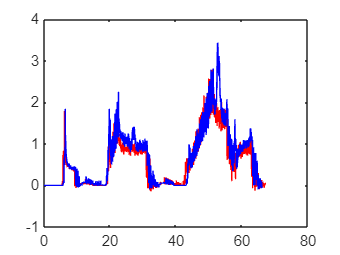

figure
plot(time_curr,tb_curr.data,'r', time_curr_lc,tb_curr_lc.data,'b')

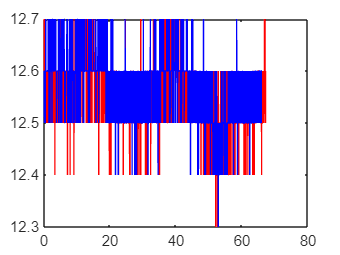

figure
plot(time_volt,tb_volt.data,'r', time_volt_lc,tb_volt_lc.data,'b')

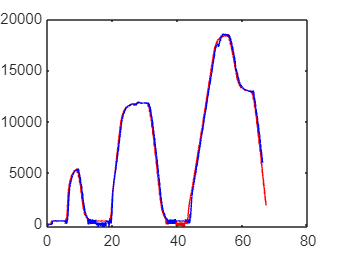

figure
plot(time_erpm,tb_erpm.data,'r', time_erpm_lc,tb_erpm_lc.data,'b')

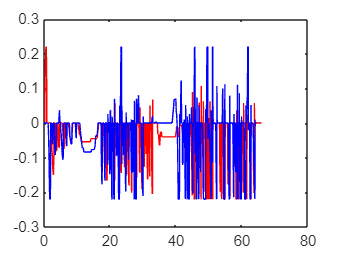

figure
plot(time_servo,tb_servo.data,'r',time_servo_lc,tb_servo_lc.data,'b')

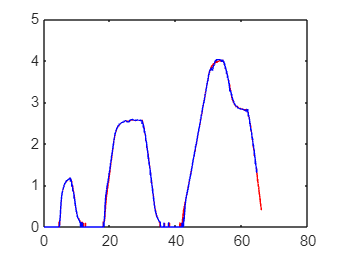

figure
plot(time_speed,act_speed,'r', time_speed_lc,act_speed_lc,'b')

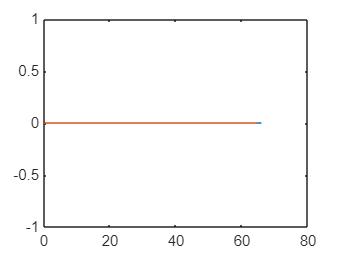

figure
plot(time_cmd,cmd_speed, time_cmd_lc,cmd_speed_lc)


figure
len_t=min(length(time_volt),length(time_curr))
len_tlc=min(length(time_volt_lc),length(time_curr_lc))
plot(time_volt(1:len_t),tb_volt.data(1:len_t).*tb_curr.data(1:len_t),'r')
  hold on;plot(time_volt_lc(1:len_tlc),tb_volt_lc.data(1:len_tlc).*tb_curr_lc.data(1:len_tlc),'b')

  figure
  plot(time_volt(1:len_t),mean(tb_volt.data(1:len_t))*ones(len_t).*tb_curr.data(1:len_t),'r')
  hold on;plot(time_volt_lc(1:len_tlc),mean(tb_volt.data(1:len_t))*ones(len_tlc).*tb_curr_lc.data(1:len_tlc),'b')

dis=cumtrapz(time_speed,act_speed);
Distance_travelled=dis(end)

Distance_travelled = 99.1581

dis_lc=cumtrapz(time_speed_lc,act_speed_lc);
Distance_travelled_lc=dis_lc(end)

Distance_travelled_lc = 98.0135

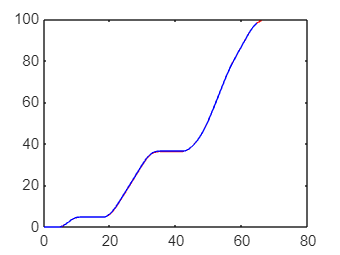

figure
plot(time_speed, dis,'r')
hold on
plot(time_speed_lc, dis_lc,'b')

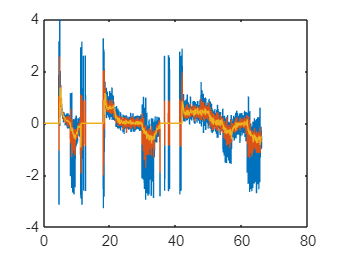

acc = gradient(act_speed(:)) ./ gradient(time_speed(:));
figure;plot(time_speed,acc)
acc_s=smoothdata(acc);
hold on;plot(time_speed,acc_s)
acc_ss=medfilt1(acc_s,10);
hold on;plot(time_speed,acc_ss)

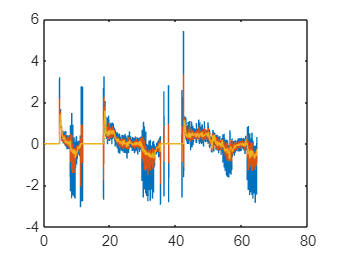


acc_lc = gradient(act_speed_lc(:)) ./ gradient(time_speed_lc(:));
figure;plot(time_speed_lc,acc_lc)
acc_s_lc=smoothdata(acc_lc);
hold on;plot(time_speed_lc,acc_s_lc)
acc_ss_lc=medfilt1(acc_s_lc,10);
hold on;plot(time_speed_lc,acc_ss_lc)

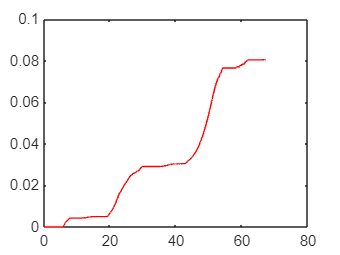

% Distance_travelled=200
% Distance_travelled_lc=200
Eb_max=27.97;%31.36;%29.32%13.36%57.7%Wh
curr=tb_curr.data;
curr(acc_ss<0)=0;

currlc=tb_curr_lc.data;
currlc(acc_ss_lc<0)=0;

pwr=mean(tb_volt.data(1:len_t))*ones(len_t).*curr;%tb_curr.data(1:len_t);% %tb_volt.data(1:len_t)
energy=cumtrapz(time_volt(1:len_t),pwr);
figure
 plot(time_volt(1:len_t),energy/3600,'r')


energy=energy(end)/3600

energy = 0.0805

range=(Eb_max*Distance_travelled/energy)*1e-3*1.1%(90/80)

range = 37.9207

 Wh_m=energy/Distance_travelled

Wh_m = 8.1135e-04



pwr_lc=mean(tb_volt.data(1:len_t))*ones(len_tlc).*currlc;%tb_curr_lc.data(1:len_tlc);%% tb_volt_lc.data(1:len_tlc)
energy_lc=cumtrapz(time_volt_lc(1:len_tlc),pwr_lc);
energy_lc=energy_lc(end)/3600

energy_lc = 0.0825

range_lc=(Eb_max*Distance_travelled_lc/energy_lc)*1e-3*1.1

range_lc = 36.5445

Wh_m = 8.4191e-04

Distance_travelled_lc = 108.6522

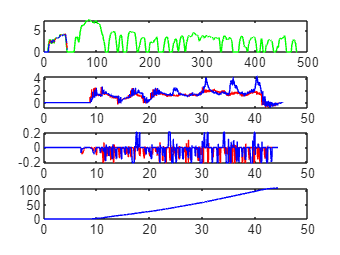

 Wh_m=energy_lc/Distance_travelled_lc